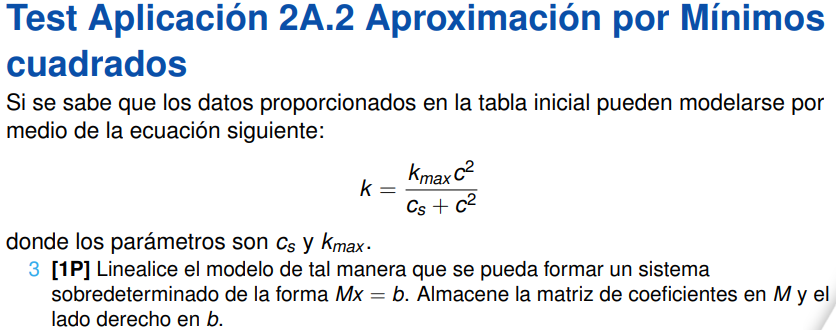

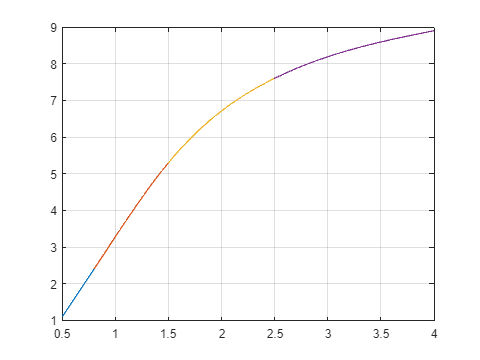

c_val=[0.5 0.8 1.5 2.5 4];
k_val=[1.1 2.4 5.3 7.6 8.9];

cTarget = [0.52 0.64 0.9 1.45 2.6 3];
resultados = zeros(size(cTarget));
S = splinenatural(c_val,k_val);


for i = 1:length(cTarget)
    indice= buscarC(cTarget(i), c_val);
    resultados(i)=reemplazar_splin_natural(cTarget(i), S(indice,:),c_val(indice));
end

k1=resultados(1)

k1 =    1.186181715360030


k2=resultados(2)

k2 =    1.703999434480165


k3=resultados(3)

k3 =    2.839803998756863


k4=resultados(4)

k4 =    5.121624451811181


k5=resultados(5)

k5 =    7.736970844143636


k6=resultados(6)

k6 =    8.188210727043215




c=[0.5; 0.8; 1.5; 2.5; 4];
k=[1.1; 2.4; 5.3; 7.6; 8.9];



M = [c.^2 -1*k]

M =    0.250000000000000  -1.100000000000000
   0.640000000000000  -2.400000000000000
   2.250000000000000  -5.300000000000000
   6.250000000000000  -7.600000000000000
  16.000000000000000  -8.900000000000000


b = (k).*(c.^2)

b = 1.0e+02 *

   0.002750000000000
   0.015360000000000
   0.119250000000000
   0.475000000000000
   1.424000000000000


sol1 = inv(M'*M)*M'*b

sol1 =   10.010248491812225
   1.993231191528652



[Q,R] = gs_c(M);

sol2 = sustireg(R,Q'*b)

sol2 =   10.010248491812224
   1.993231191528651



vdif = [abs(sol2-sol1)]'

vdif = 1.0e-14 *

   0.177635683940025   0.155431223447522


kmax = sol2(1)

kmax =   10.010248491812224


cs = sol2(2)

cs =    1.993231191528651



k = @(c)((kmax*c*c)/(cs + c*c));

k5_gs = k(2.6)

k5_gs =    7.730777163767905


k6_gs = k(3)

k6_gs =    8.195246225307697



vdif2 = [abs(k5 - k5_gs) abs(k6 - k6_gs)]

vdif2 =    0.006193680375731   0.007035498264482


function [x]=sustireg(Ea,b)
U = triu(Ea);
% U: Matriz triangular superior
[m,n]=size(U);
x=zeros(n,1);
for k=n:-1:1
x(k)=(b(k)- U(k,k+1:n)*x(k+1:n))/U(k,k);
end
end


function [Q, R]=gs_c(A)
    [m,n]=size(A);
    Q=zeros(m,n);
    R=zeros(n);
    for j=1:n
        R(1:j-1,j)=Q(:,1:j-1)'*A(:,j);
        temp=A(:,j)-Q(:,1:j-1)*R(1:j-1,j);
        R(j,j)=norm(temp);
        Q(:,j)=temp/R(j,j);
    end
end



function S=splinenatural(X,Y)
N=length(X)-1;
H=diff(X);
E=diff(Y)./H;
diagprinc=2*(H(1:N-1)+H(2:N));
diagsupinf=H(2:N-1);
g0=0; gn=0;
A=diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
b=6*diff(E');
g=A\b;
g=[g0 g' gn ];
for i=1:N
    S(i,1)=(g(i+1)-g(i))/(6*H(i));
    S(i,2)=g(i)/2;
    S(i,3)=E(i)-H(i)*(g(i+1)+2*g(i))/6;
    S(i,4)=Y(i);
    xx=linspace(X(i),X(i+1),100);
    yy=S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
    plot(xx,yy)
    hold on
end
grid on
hold off
end

function indice = buscarC( valor_c, vector_c )
indice = 1;
i=1;
while(vector_c(i)<=valor_c)
    indice = i;
    i = i+1;
end
end


function valor_k = reemplazar_splin_natural(valor_c, coeficientes,limite_inferior)

n = length(coeficientes)-1;
syms x
poly=0;
for i= 1:n+1
    poly = coeficientes(i)*(x-limite_inferior)^(n+1-i)+poly;
end

valor_k = double(   subs(poly,valor_c) );

end

